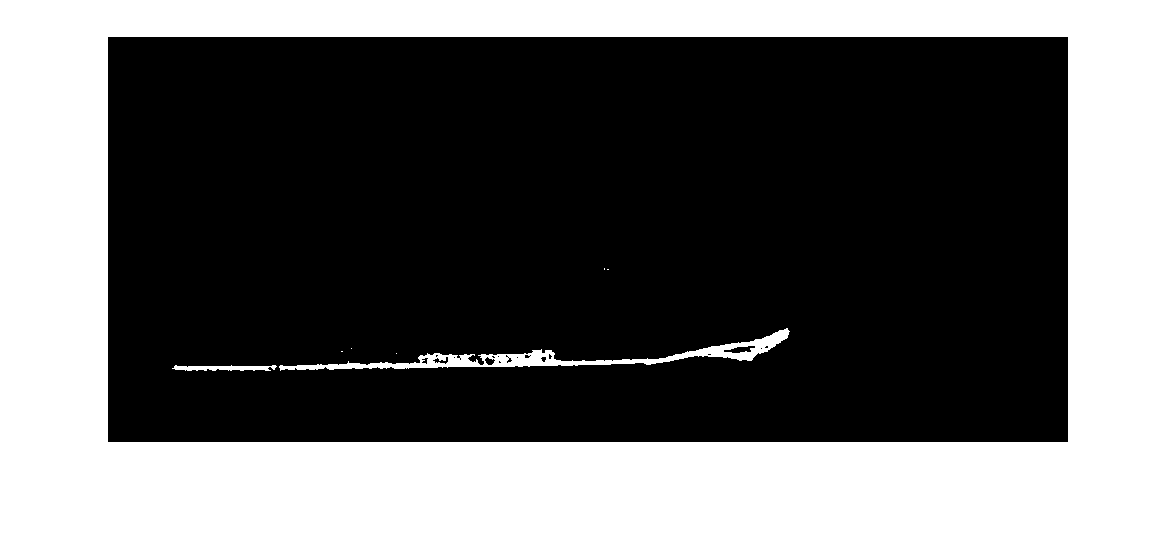

%cam = webcam('HD Pro Webcam C920');



%Capture = imresize(snapshot(cam), 1);
FilimentMask = @OrangeMask2;

Filiment = FilimentMask(Capture(1:round(end*0.75), :, :));
Filiment = medfilt2(Filiment,[1, 1]);

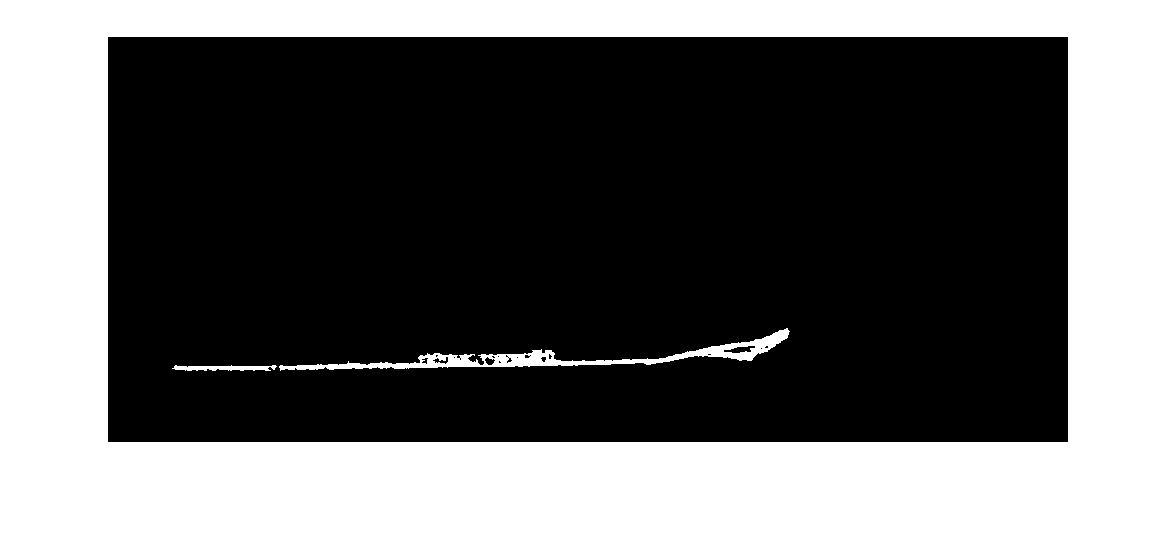

info = regionprops(Filiment, 'Area');
Filiment = bwareaopen(Filiment, info(1).Area - 1);
imshow(Filiment)

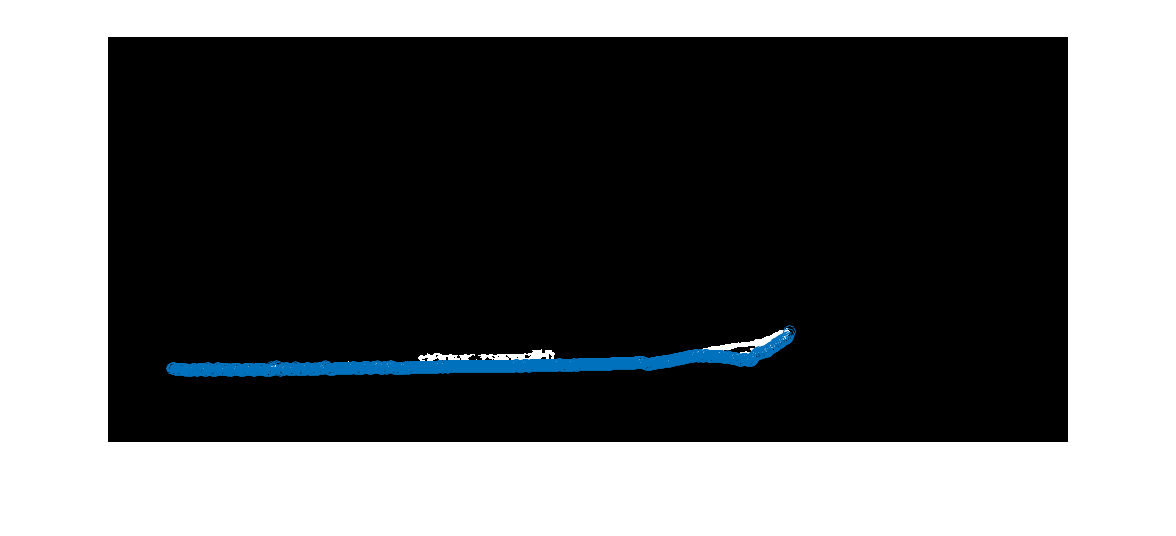

BW = Filiment;
[r,c] = find(BW);
x = [];
y = [];
for i = 1:size(BW, 2)
    V = find(BW(:,i));
    if(isempty(V))
        continue;
    end
    y = [y;max(V)];
    x = [x; i];
end
figure, imshow(BW)
hold on
scatter(x,y)

yin= y;
xin = x;
ind = isoutlier(yin);
yin(ind)=[];
xin(ind) = [];
M = ones(length(yin),2);
M(:,2) = xin;
v = (M' * M)^-1*M'*yin;

Result = sum((y - (x * v(2) +v(1))).^2)/(length(x))

Result = 17.4049